# Generate classes/labels from an image by segmengting it

Creation:               08-01-2017

Last modification: 11-01-2017

Authors: 

- Eldad Haber, 

- Luz Angelica Caudillo Mata

## Introducton

This scripts visualizes a particular data set and the classes associated to it. The dataset we work with corresponds to an image. The image has been previously segmented into three types of objects: background, clear chips, and dark chips. These types of objects constitute the classes/labes for our dataset. 

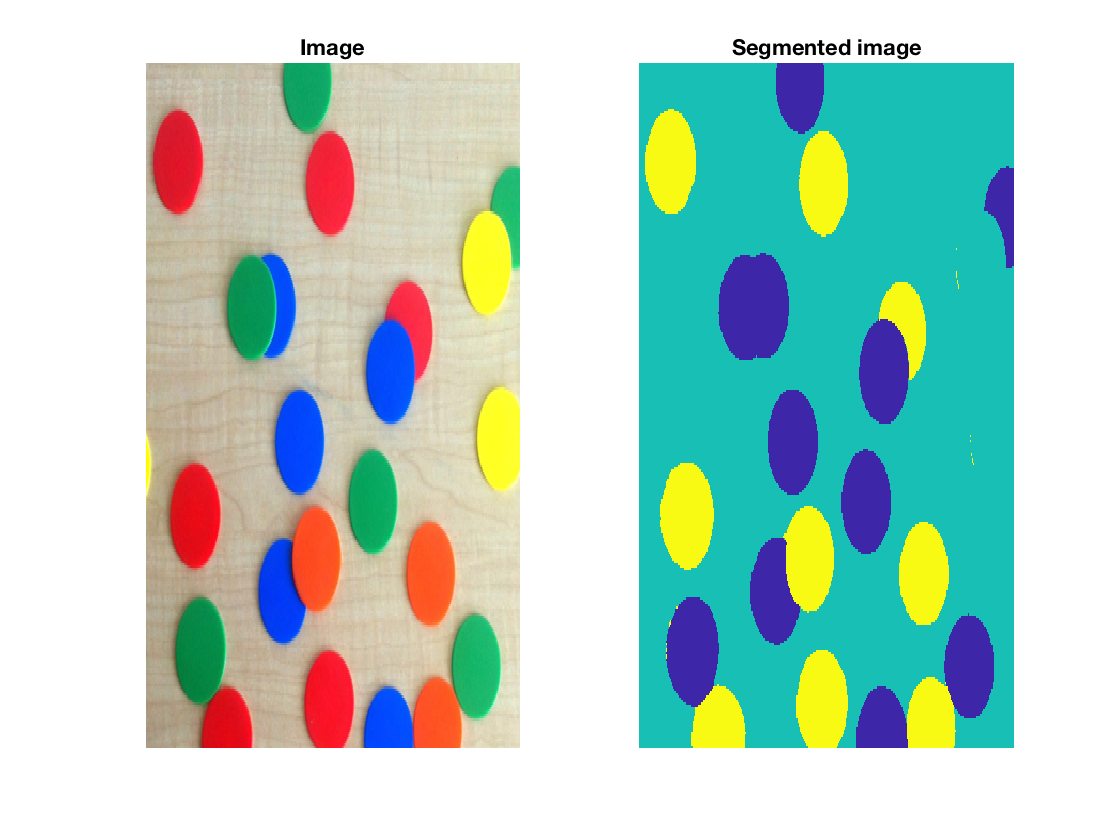

% Clear workspace
clear 
clc
close all

% Pre-define functions we will use later on
vec = @(x) x(:);

% Visualize image
% Note: a truecolor image returns an array as an M-by-N-by-3 array due to its RGB color model
I = imread('coloredChips.png');
I = I(1:300,101:450,:);
subplot(1,2,1)
imagesc(I);
title('Image')
axis off;

% Visualize segmented image
% Note: segmented image is already provided as a *.mat file. 
load imgSeg
subplot(1,2,2)
imagesc(imgSeg);
title('Segmented image')
axis off;

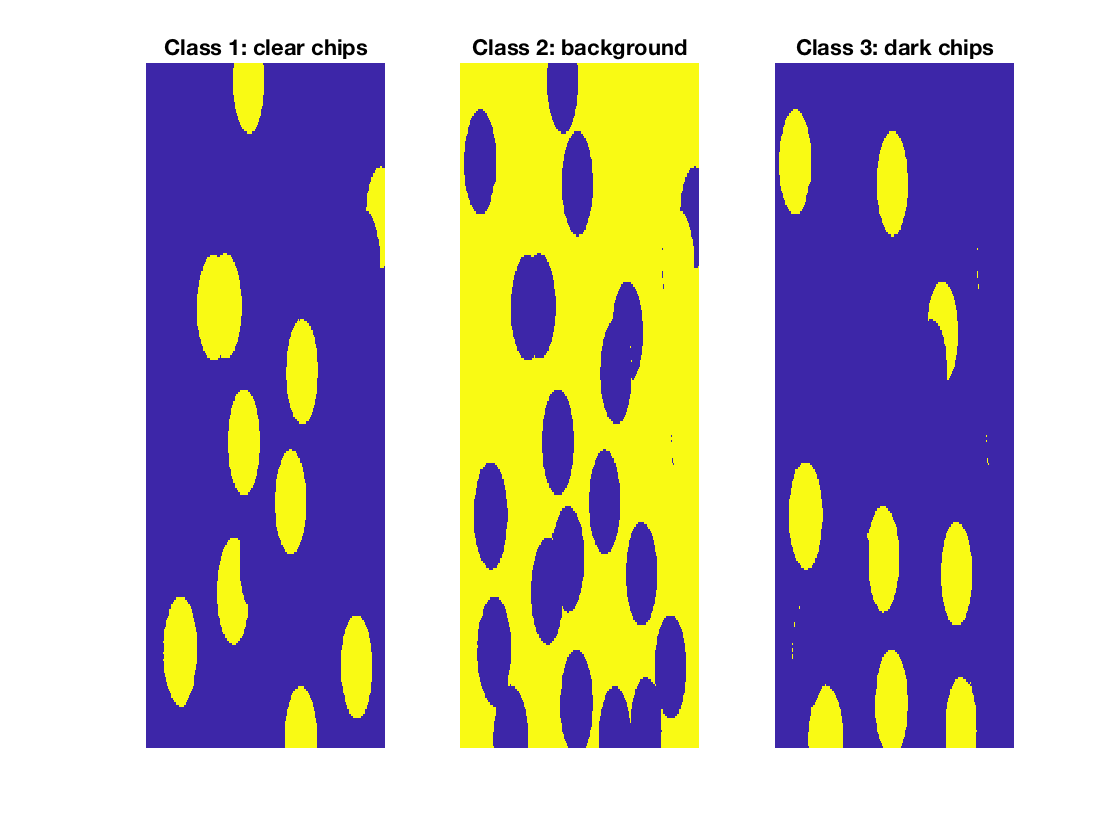

% Visualize segmented image in the RGB colormap space
RGB = [vec(I(:,:,1)), vec(I(:,:,2)), vec(I(:,:,3))];

% imgSeg contains three classes: 1 (clear chips), 2 (background) or 3 (dark chip).
i1 = imgSeg==1;
i2 = imgSeg==2;
i3 = imgSeg==3;

% Visualize boolean arrays
subplot(1,3,1)
imagesc(i1)
title('Class 1: clear chips')
axis off

subplot(1,3,2)
imagesc(i2)
title('Class 2: background')
axis off

subplot(1,3,3)
imagesc(i3)
title('Class 3: dark chips')
axis off

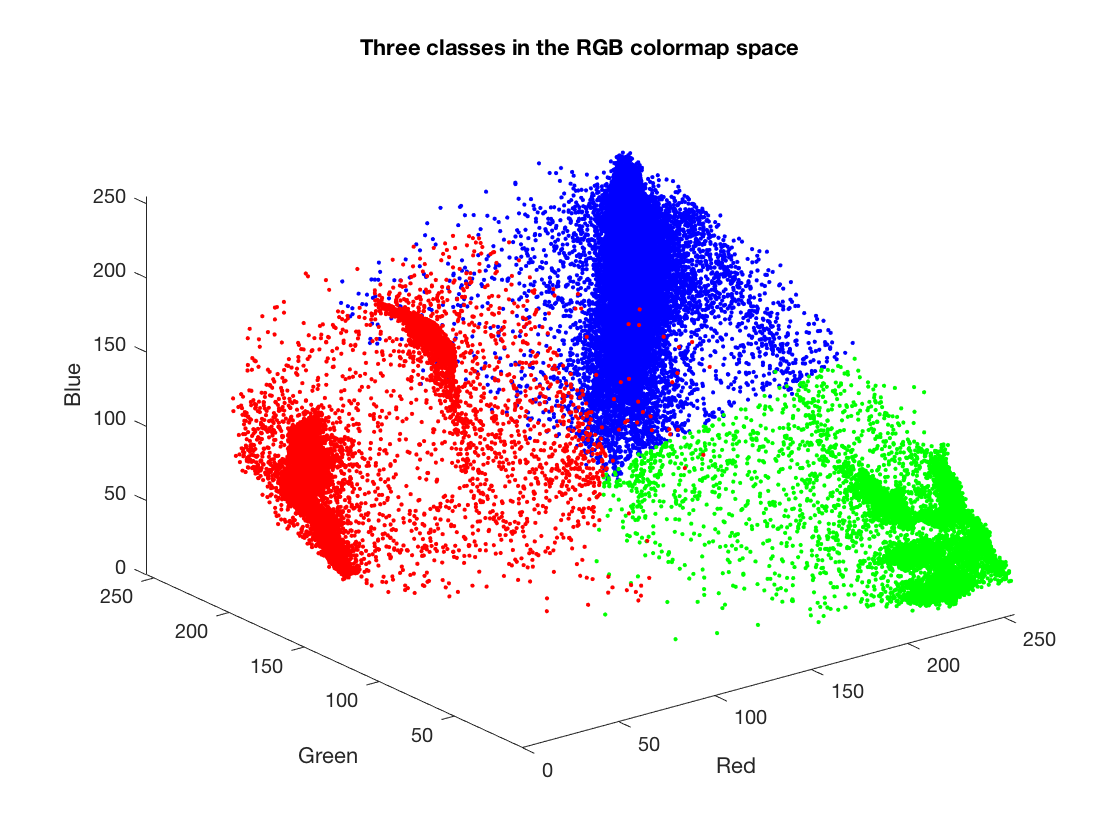

% Visualize each class in the RGB colormap space
plot3(RGB(i1,1),RGB(i1,2),RGB(i1,3),'.r')
hold on
plot3(RGB(i2,1),RGB(i2,2),RGB(i2,3),'.b')
hold on
plot3(RGB(i3,1),RGB(i3,2),RGB(i3,3),'.g')
hold off
axis tight

xlabel('Red')
ylabel('Green')
zlabel('Blue')
title('Three classes in the RGB colormap space');

## Conclusion

In this example, we used a dataset from an image and by segmenting it we created classes/labels associated to that image.  We visualized the image, the segmented image and its associated classes. The newly generated classes will be used later on in the course to construct predictive models. 